# Solve DAE for a gantry crane

See the pendulum example in documentation:

- [https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html](https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html)

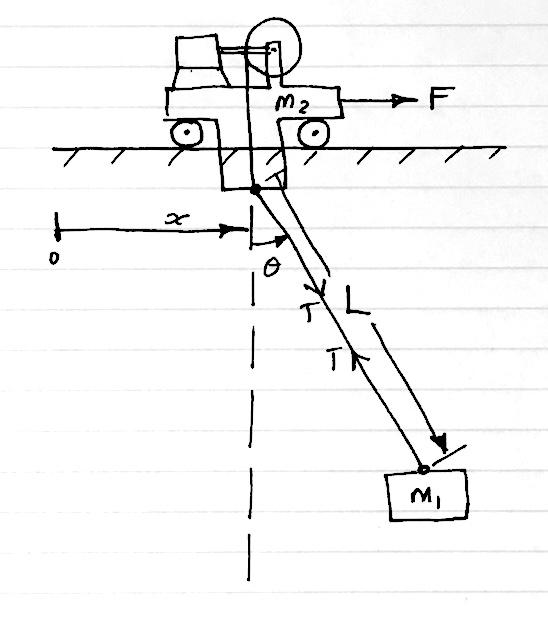

State variables

- Horizontal position of pendulum $x\left(t\right)$

- Angle of cable $\theta \left(t\right)$

- Length of cable $L\left(t\right)$

- Tension in cable $T\left(t\right)$

System input variables

- Driving force on trolley $F\left(t\right)$

- Speed of cable leaving winch $v\left(t\right)=\dot{L} \left(t\right)$

Parameters

- Load mass $m_1$

- Trolley mass $m_2$

- Pendulum length $r$

- Gravitational constant $g$

DAE system of equations


$$\begin{array}{l}
m_2 \frac{d^{2\;} x\left(t\right)}{{\mathrm{dt}}^{2\;} }=F\left(t\right)+T\left(t\right)\;\sin \left(\theta \left(t\right)\right)\\
m_1 \frac{d^{2\;} \theta \left(t\right)}{{\mathrm{dt}}^{2\;} }=-m_1 \;g\;\sin \left(\theta \left(t\right)\right)\\
m_1 \frac{d^{2\;} L\left(t\right)}{{\mathrm{dt}}^{2\;} }=-T\left(t\right)+m_1 \;g\;\cos \left(\theta \left(t\right)\right)
\end{array}$$


clear variables

## First, define an autonomous system

i.e. `F(t) = 0`, `L(t) = l` (constant)

% Define symbolic variables
syms x(t) theta(t) F(t) m1 m2 g l

% Force balance of trolley and cable
%eqn1 = m2*diff(x(t), 2) == T(t)*sin(theta(t))
eqn1 = m2*diff(x(t), 2) == m1*g*sin(2*theta(t))/2

$$eqn1 = m_{2}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=0.5000\,g\,m_{1}\,\sin\left(2\,\theta \left(t\right)\right)$$

% Force balance of load and cable
eqn2 = m1*diff(theta(t), 2) == - m1*g*sin(theta(t))

$$eqn2 = m_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-g\,m_{1}\,\sin\left(\theta \left(t\right)\right)$$

%eqn3 = m1*diff(L(t), 2) == -T(t) + m1*g*cos(theta(t))
% (eliminated)
% Energy balance (kinetic + potential)
% eqn4 = m1*diff(x(t))^2 + m2*diff(L(t))^2 + ...
%     m2*L(t)*diff(theta(t))^2 == m2*g*L(t)*(1 - cos(theta(t)))
%eqn4 = m1*diff(x(t))^2 + m2*L(t)*diff(theta(t))^2 == m2*g*l*(1 - cos(theta(t)))
eqns = [eqn1 eqn2];
%vars = [x(t); theta(t); L(t); T(t)];
vars = [x(t); theta(t)];
origVars = length(vars)

origVars = 2

Check Incidence of Variables

M = incidenceMatrix(eqns, vars)

M =      1     1
     0     1


Reduce Differential Order

[eqns, vars] = reduceDifferentialOrder(eqns, vars)

$$eqns = \left(\begin{array}{c} m_{2}\,\frac{\partial }{\partial t}\mathrm{Dxt}\left(t\right)-0.5000\,g\,m_{1}\,\sin\left(2\,\theta \left(t\right)\right)\\ m_{1}\,\frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)+g\,m_{1}\,\sin\left(\theta \left(t\right)\right)\\ \mathrm{Dxt}\left(t\right)-\frac{\partial }{\partial t}x\left(t\right)\\ \mathrm{Dthetat}\left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Check Differential Index of System

if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")

Reduce Differential Index with reduceDAEIndex

    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)

Eliminate redundant equations and variables

    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)

Check the differential index of the new system

    assert(isLowIndexDAE(DAEs, DAEvars))

$$extraParams = \left(\begin{array}{ccc} g & m_{1} & m_{2} \end{array}\right)$$

else
    DAEs = eqns;
    DAEvars = vars;
end

### Convert DAE system to MATLAB function

pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

Create the function handle

f = daeFunction(DAEs, DAEvars, g, m1, m2);

### Set parameter values

g = 9.81;
m1 = 10;
m2 = 20;

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

l = 2;

Create function for ode15i

F = @(t, Y, YP) f(t, Y, YP, g, m1, m2);

### Find initial condition

DAEvars

Note that `Dxt(t)`, `Dthetat(t)`, `DLt(t)` are the first derivatives of `x(t)` ... etc.

Provide an estimate of the initial condition

% pi/6 = 30 deg
% Variables
%x0est = [0; pi/6; 2; 9*200; 0; 0; 0];

x0 =          0
    0.5236
         0
         0


xp0 =          0
         0
    2.1239
   -4.9050


x0est = [0; pi/6; 0; 0];
% Their derivatives
xp0est = zeros(4, 1);

Set tolerances and do numerical search.

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[x0, xp0] = decic(F, 0, x0est, [], xp0est, [], opt)

### Solve DAEs Using ode15i

opt = odeset('RelTol', 10.0^(-5), 'AbsTol', 10.0^(-5));
[tSol, xSol] = ode15i(F, [0 5], x0, xp0, opt);

Plot solution

plot(tSol, xSol(:, 1:origVars), 'LineWidth', 2)
xlabel("Time ($t$)", 'Interpreter', 'latex')
labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);

legend(labels, 'Location', 'Best', 'Interpreter', 'latex')
grid on

## Autonomous system with trolley friction

Also, add `T(t)` back in as an extra variable and centripetal force.

% Define symbolic variables
syms x(t) theta(t) L(t) F(t) T(t) m1 m2 g Kf l
% Horizontal force balance of trolley with kinetic friction (+ve to right)
eqn1 = m2*diff(x(t), 2) == 1000*T(t)*sin(theta(t)) - ...
    1000*T(t)*Kf*cos(theta(t))*diff(x(t), 1)

$$eqn1 = m_{2}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=1000\,\sin\left(\theta \left(t\right)\right)\,T\left(t\right)-1000\,\mathrm{Kf}\,\cos\left(\theta \left(t\right)\right)\,T\left(t\right)\,\frac{\partial }{\partial t}x\left(t\right)$$

% More accurate alterantive
%    1000*abs(T(t))*Kf*cos(theta(t))*sign(diff(x(t), 1))
% Force balance of load - tangential (anti-clockwise +ve)
eqn2 = m1*diff(theta(t), 2) == - m1*g*sin(theta(t))

$$eqn2 = m_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-g\,m_{1}\,\sin\left(\theta \left(t\right)\right)$$

% Force balance of load - radial
eqn3 = 1000*T(t) == m1*g*cos(theta(t)) + m1*l*diff(theta(t), 1)^2

$$eqn3 = 1000\,T\left(t\right)=l\,m_{1}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+g\,m_{1}\,\cos\left(\theta \left(t\right)\right)$$

eqns = [eqn1 eqn2 eqn3];
%vars = [x(t); theta(t); L(t); T(t)];
vars = [x(t); theta(t); T(t)];
origVars = length(vars)

origVars = 3

% Check equations at certain points
s = struct();
% Cart is not accelerating when theta = 0 and diff(x(t), t) = 0
s.vars = {theta(t), diff(x(t))};
s.values = {0, 0};
assert(rhs(subs(eqn1, s.vars, s.values)) == 0)
% Cart horiz. force = T(t) when theta = pi/2, diff(x(t), t) = 0
s.vars = {theta(t), diff(x(t), 1)};
s.values = {pi/2, 0};
assert(rhs(subs(eqn1, s.vars, s.values)) == 1000*T(t))
% Cable tension T(t) = weight of m2 when theta(t) = 0, diff(theta(t), 2) = 0
s.vars = {theta(t), diff(theta(t), 1)};
s.values = {0, 0};
assert(rhs(subs(eqn3, s.vars, s.values)) == g*m1)
% Check friction force is negative when diff(x(t)) > 0
s.vars = {theta(t), diff(x(t)), T(t), Kf};
s.values = {0, 0.1, 0.2, 0.6};
assert(rhs(subs(eqn1, s.vars, s.values)) < 0)
% Check friction force is positive when diff(x(t)) < 0
s.vars = {theta(t), diff(x(t)), T(t), Kf};
s.values = {0, -0.1, 0.2, 0.6};
assert(rhs(subs(eqn1, s.vars, s.values)) > 0)

% Check Incidence of Variables
M = incidenceMatrix(eqns, vars)

M =      1     1     1
     0     1     0
     0     1     1


% Reduce Differential Order
[eqns, vars] = reduceDifferentialOrder(eqns, vars)

$$eqns = \left(\begin{array}{c} m_{2}\,\frac{\partial }{\partial t}\mathrm{Dxt}\left(t\right)-1000\,\sin\left(\theta \left(t\right)\right)\,T\left(t\right)+1000\,\mathrm{Kf}\,\cos\left(\theta \left(t\right)\right)\,\mathrm{Dxt}\left(t\right)\,T\left(t\right)\\ m_{1}\,\frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)+g\,m_{1}\,\sin\left(\theta \left(t\right)\right)\\ -l\,m_{1}\,{\mathrm{Dthetat}\left(t\right)}^{2}+1000\,T\left(t\right)-g\,m_{1}\,\cos\left(\theta \left(t\right)\right)\\ \mathrm{Dxt}\left(t\right)-\frac{\partial }{\partial t}x\left(t\right)\\ \mathrm{Dthetat}\left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ T\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

% Check Differential Index of System
if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")
    % Reduce Differential Index with reduceDAEIndex
    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)
    % Eliminate redundant equations and variables
    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)
    % Check the differential index of the new system
    assert(isLowIndexDAE(DAEs, DAEvars))
else
    DAEs = eqns;
    DAEvars = vars;
end
DAEvars

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ T\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

% Convert DAE system to MATLAB function
pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

$$extraParams = \left(\begin{array}{ccccc} \mathrm{Kf} & g & l & m_{1} & m_{2} \end{array}\right)$$

% Create the function handle
f = daeFunction(DAEs, DAEvars, Kf, g, l, m1, m2);

### Estimate initial condition and solve

% Set parameter values
Kf = 0.2;
g = 9.81;
l = 2;
m1 = 10;
m2 = 20;
% Create function for ode15i
F = @(t, Y, YP) f(t, Y, YP, Kf, g, l, m1, m2);
% Provide an estimate of the initial condition
% Variables
x0est = [0; pi/12; g*m2/1000; 0; 0];
% Their derivatives
xp0est = [0; 0; 0; 1; -2];
% Set tolerances and do numerical search.
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
% Find initial condition numerically
[x0, xp0] = decic(F, 0, x0est, [], xp0est, [], opt)

x0 =          0
    0.2618
    0.0948
         0
         0


xp0 =          0
         0
         0
    1.2263
   -2.5390


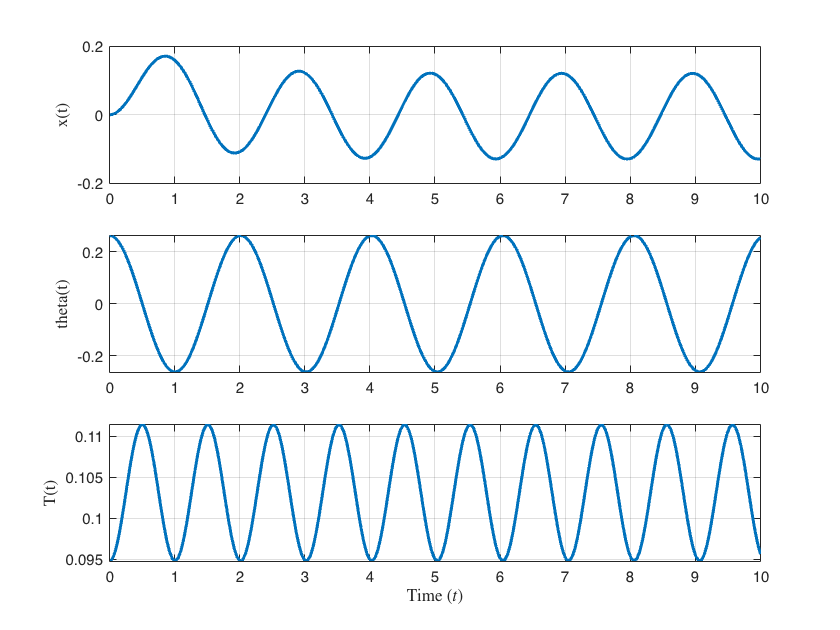

% Solve DAEs Using ode15i
opt = odeset('RelTol', 10.0^(-5), 'AbsTol', 10.0^(-5));
[tSol, xSol] = ode15i(F, [0 10], x0, xp0, opt);
% Plot solution
figure(1); clf
% labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);
for i = 1:origVars
    subplot(origVars, 1, i);
    plot(tSol, xSol(:, i), 'LineWidth', 2); hold on
    ylabel(char(DAEvars(i)), 'Interpreter', 'latex')
    grid on
end
xlabel("Time ($t$)", 'Interpreter', 'latex')

%legend(labels, 'Location', 'Best', 'Interpreter', 'latex')